Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Digital Signal Processing Laboratory Experiment - 8**

% making the value of heaviside() at origin equal to 1
sympref('HeavisideAtOrigin', 1);
u = @(n) heaviside(n);

% defining the DTFT function
dtft = @(xn, n, w) xn * exp(-1j .* (n' * w));

% defining discrete time Inverse Fourier Transform
dtift = @(Xw, w, n) (Xw * exp(1j .* (w' * n))) ./ length(w);

% defining range of frequencies (omega) from -pi to +pi
w = -pi:0.01:pi;

% loading the ecg and ppg signals
load('/Users/pranayborgohain/Documents/MATLAB/Exp8/ecg_rand_signal_fs_360_10seconds.mat');
load('/Users/pranayborgohain/Documents/MATLAB/Exp8/ppg_random_noise.mat');
ecg_sampling_freq = 360; % Hz
ppg_sampling_freq = 100; % Hz
ecg_time_period = 1 ./ ecg_sampling_freq; % sec
ppg_time_period = 1 ./ ppg_sampling_freq; % sec

Q1.

For a M-point moving average filter,


$$y[n] = \frac{1}{M}\sum_{k=0}^{M-1}x[n-k]$$


(a) subtracting the time delayed signal to get the difference equation,


$$\Rightarrow y[n] -y[n-1] = \frac{1}{M}\cdot \left(\sum_{k=0}^{M-1}x[n-k] - \sum_{k=0}^{M-1}x[n-1-k]\right)$$



$$\Rightarrow y[n] -y[n-1] = \frac{1}{M}\cdot \left(\sum_{k=0}^{M-1}x[n-k] - \sum_{k=1}^{M}x[n-k]\right)$$



$$\Rightarrow y[n] -y[n-1] = \frac{1}{M}\cdot \left(x[n] - x[n-M]\right)$$


(b) Taking the z-transform on both sides,


$$\Rightarrow Y(z)\cdot(1-z^{-1}) = \frac{1}{M}\cdot X(z)\cdot(1 - z^{-M})$$


Thus, we get the Transfer Function of the system as:


$$\Rightarrow H(z) = \frac{Y(z)}{X(z)} = \frac{1}{M}\cdot \frac{(1-z^{-M})}{(1-z^{-1})}$$



$$\Rightarrow H(z) = \frac{Y(z)}{X(z)} = \frac{1}{M}\cdot \frac{(z^{M} - 1)}{z^{M-1}(z-1)}$$
 

(c) Now, replaing $z$ with $e^{j\omega}$, we get the Frequency Response:


$$\Rightarrow H(e^{j\omega}) = \frac{1}{M}\cdot \frac{(1-e^{-j\omega M})}{(1-e^{-j\omega})}$$


% Defining the transfer function
Hz_M = @(M, z) (1 ./ M) .* ((1 - z^(-M)) / (1 - z^(-1)));
% Defining the frequency response
Hw_M = @(M) (1 ./ M) .* ((1 - exp(-1j .* w .* M)) ./ (1 - exp(-1j .* w)));

(e) The above system has a pole at the origin, and at $z=1$, respectively. It has 2 zeros, at $z=1$ and $z=-1$.

In general, a M-point moving average filter will have $M-1$ poles at the origin, one pole at $z = 1$, and it's zeros will be the $M^{th}$ roots of unity.

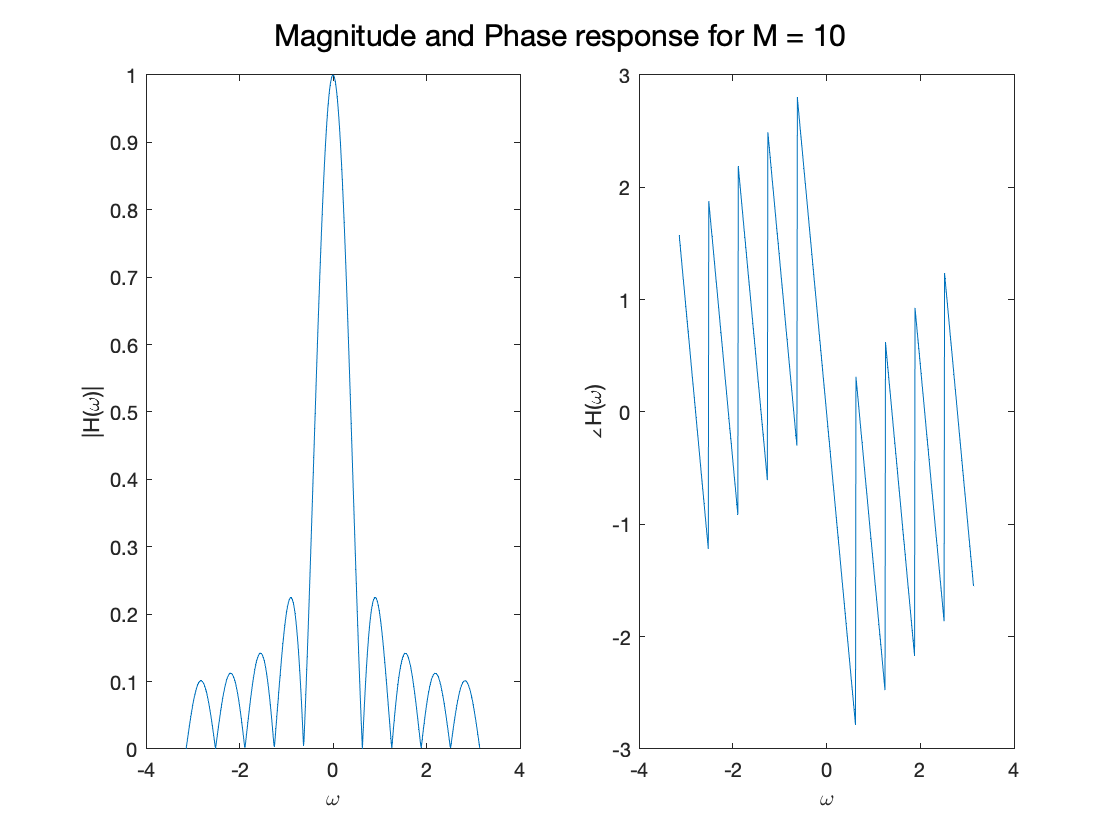

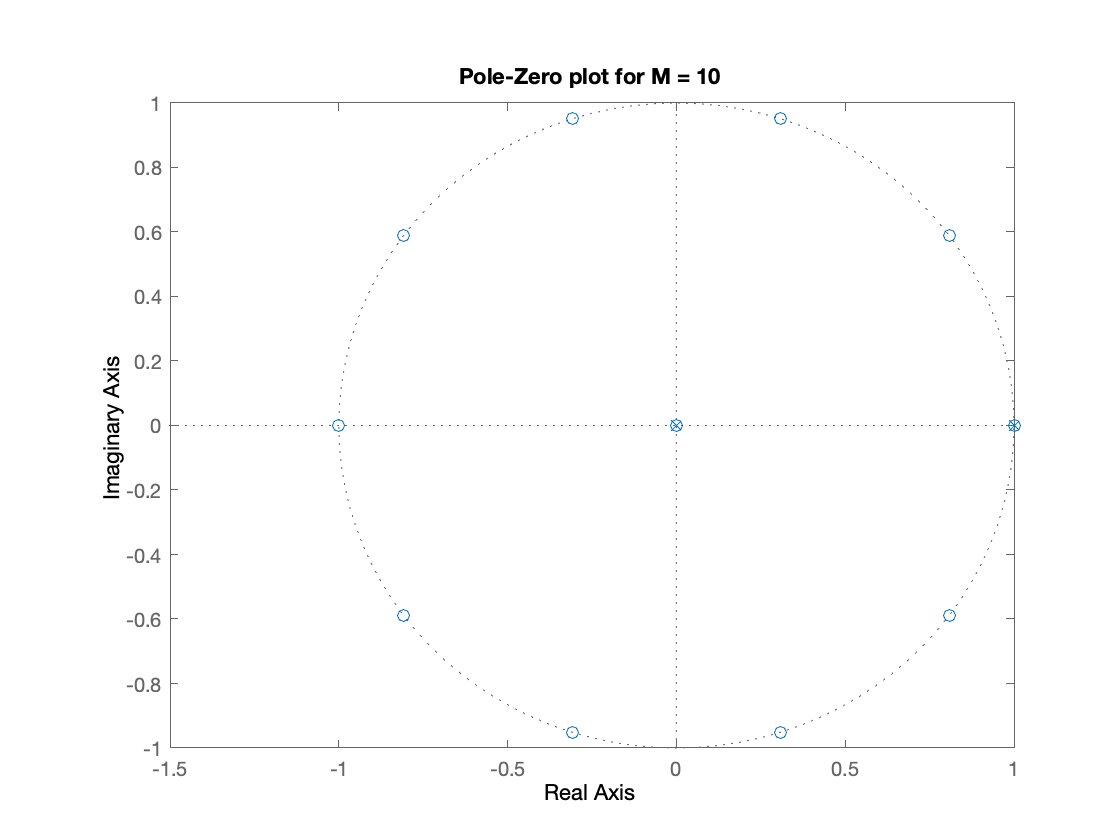

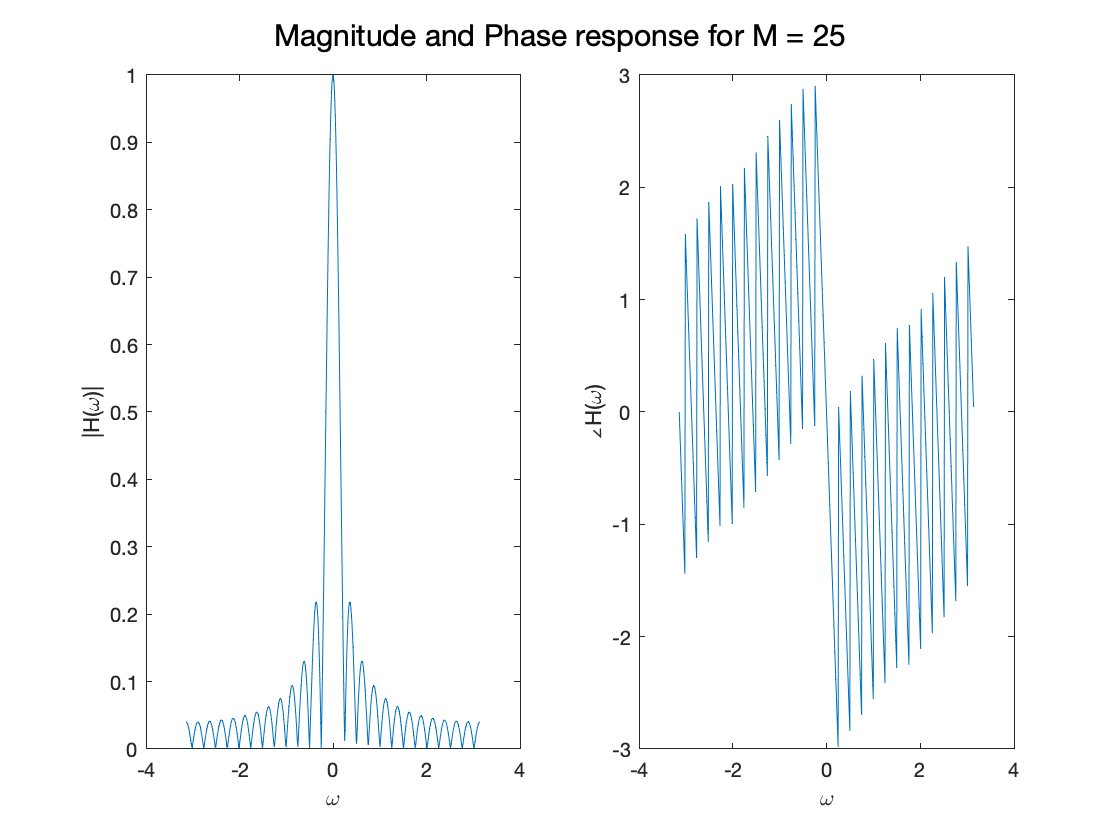

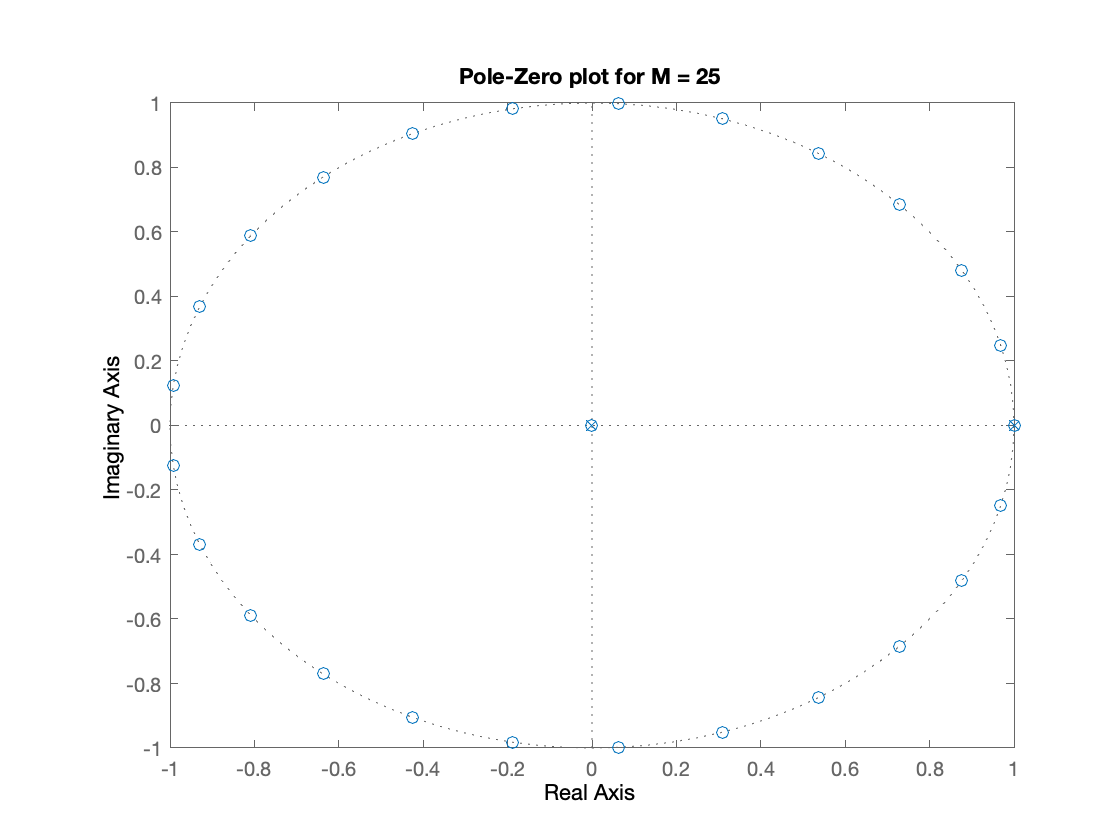

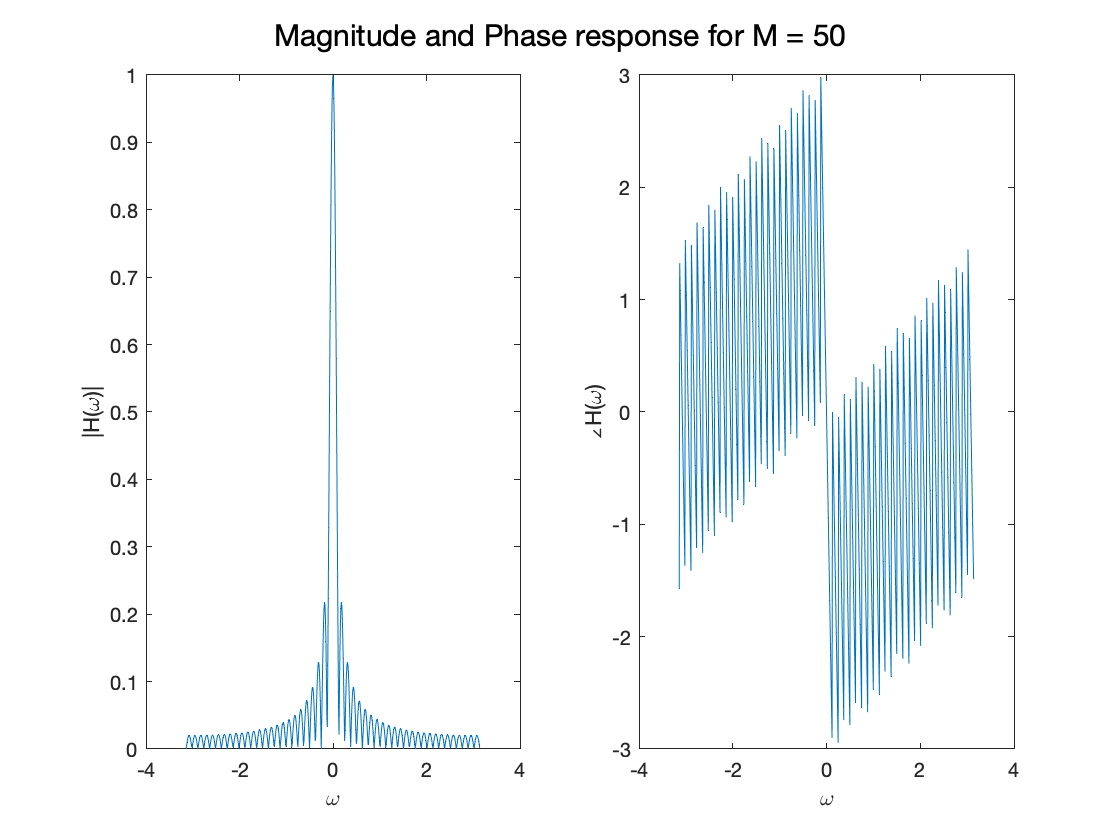

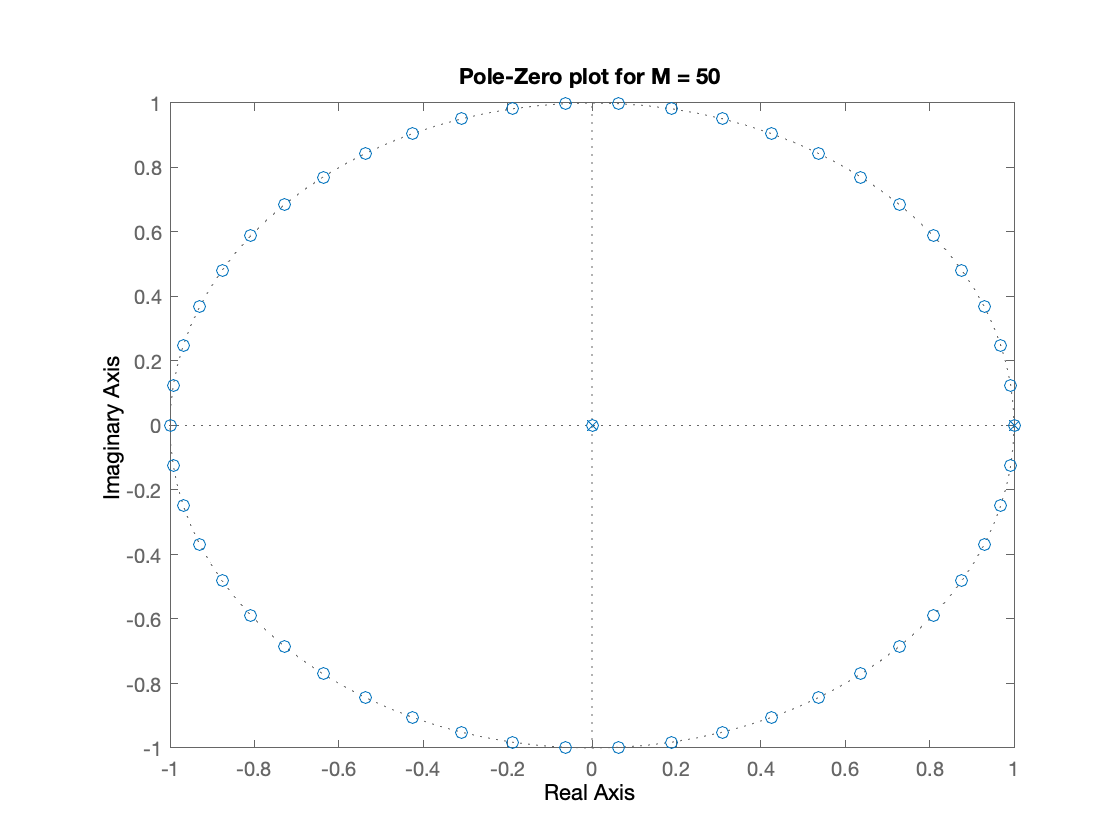

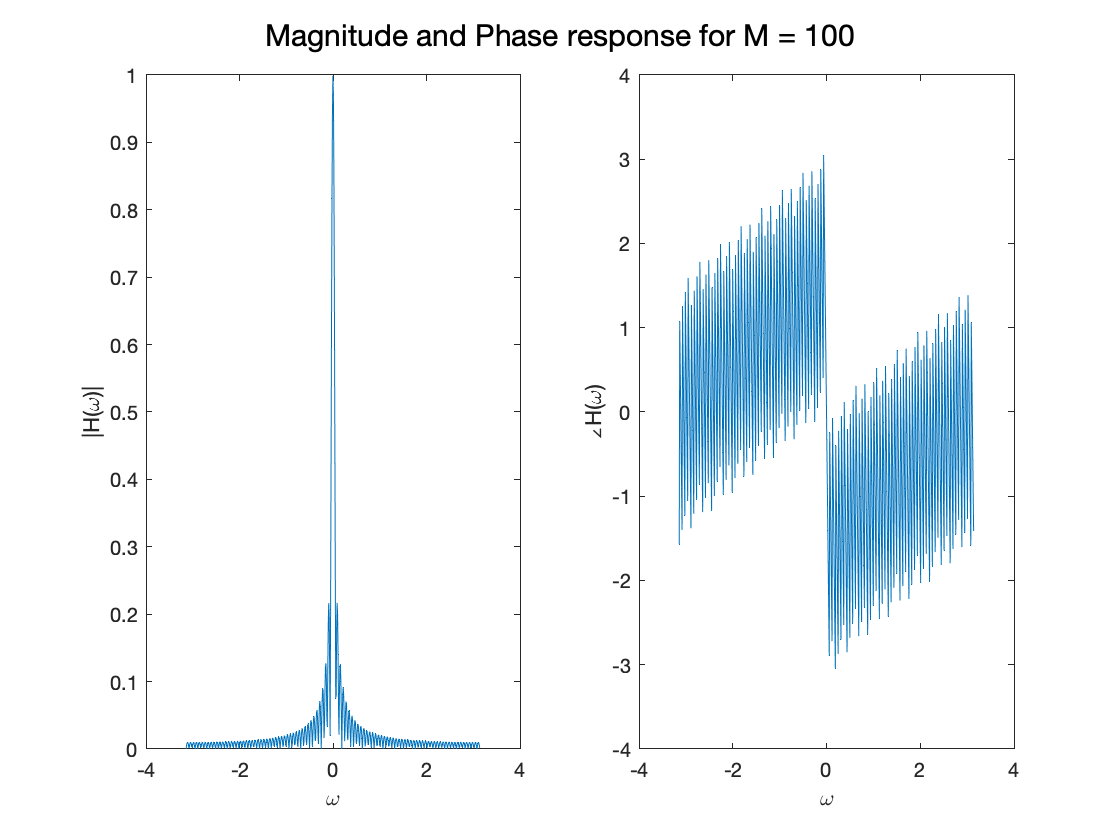

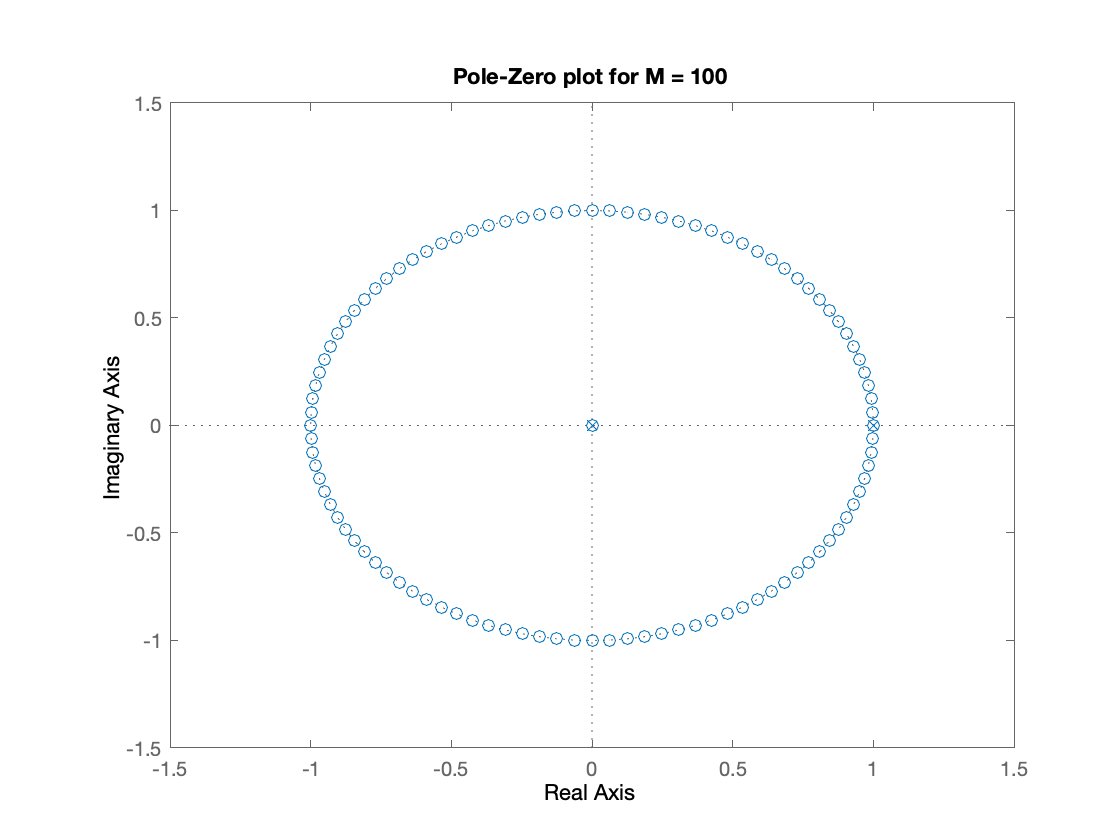

% (d), (f), (g) studying magnitude response and pole-zero plots for M = 10, 25, 50, 100
M_values = [10, 25, 50, 100];
l = length(M_values);
z = tf('z');

for i = 1:l
    Mi = M_values(i);
    Hw_Mi = Hw_M(Mi);
    
    % plotting the magnitude and phase response
    figure;
    subplot(1, 2, 1);
    plot(w, abs(Hw_Mi)); xlabel("\omega"); ylabel("|H(\omega)|");
    subplot(1, 2, 2);
    plot(w, angle(Hw_Mi)); xlabel("\omega"); ylabel("\angleH(\omega)");
    sgtitle("Magnitude and Phase response for M = " + Mi);
    
    % plotting the poles and zeros of the transfer function
    Hz_Mi = Hz_M(Mi, z);
    figure;
    pzplot(Hz_Mi);
    title("Pole-Zero plot for M = " + Mi);
end

We observe that the cutoff frequency keeps on decresing for larger values of $M$. This can be intuitively explained by the fact that for larger values of $M$, the smoothening effect is more pronounced, hence the higher frequency components are filtered out for greater values of $M$.

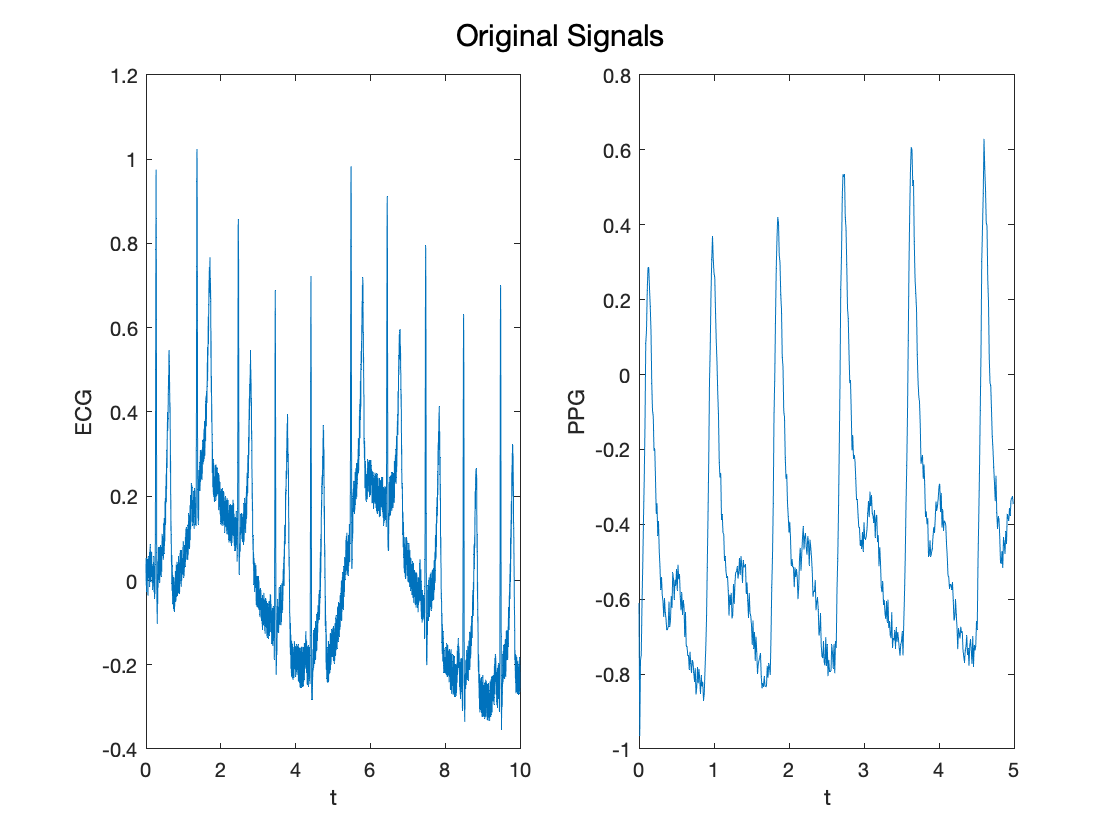

% (h)
% obtaining discrete indices for the ECG and PPG signals
ecg_n = 0:length(ecg_rang_signal)-1;
ppg_n =  0:length(ppg_random)-1;

% obtaining time indices for the ECG and PPG signals
ecg_t = ecg_n .* ecg_time_period;
ppg_t =  ppg_n .* ppg_time_period;

% plotting original signals
figure;
subplot(1, 2, 1);
plot(ecg_t, ecg_rang_signal); xlabel("t"); ylabel("ECG");
subplot(1, 2, 2);
plot(ppg_t, ppg_random); xlabel("t"); ylabel("PPG");
sgtitle("Original Signals");

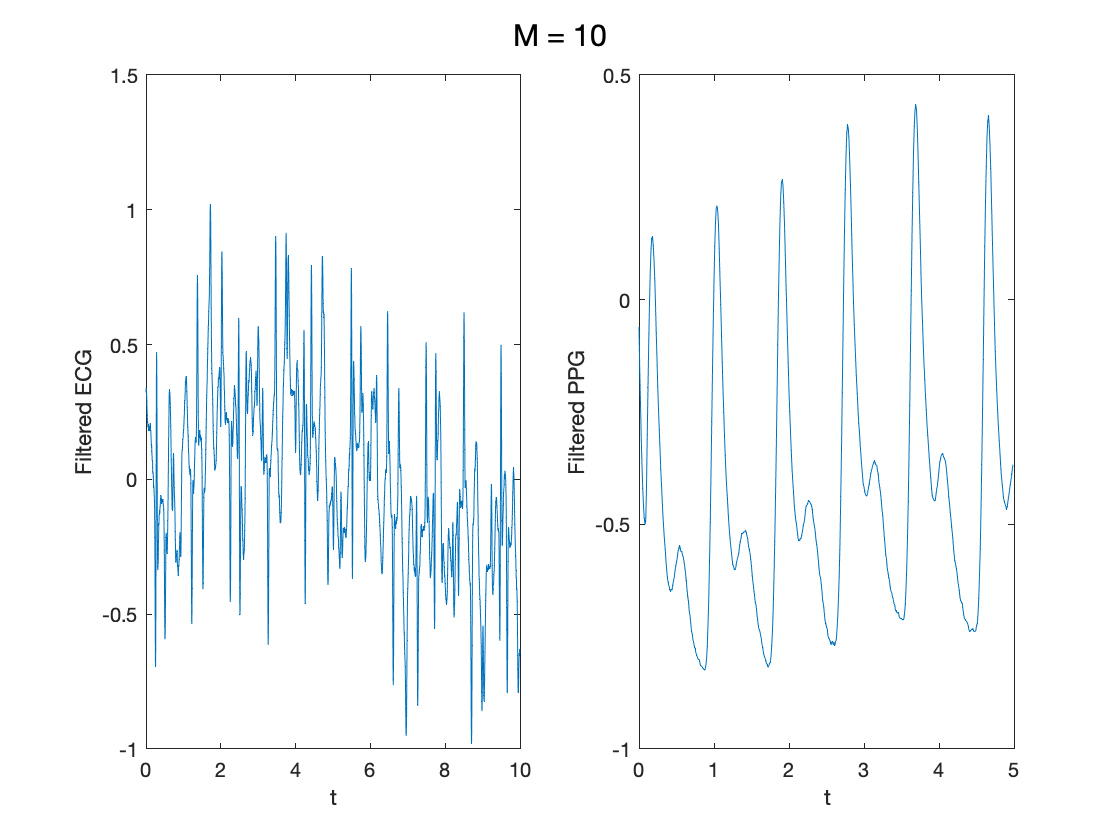

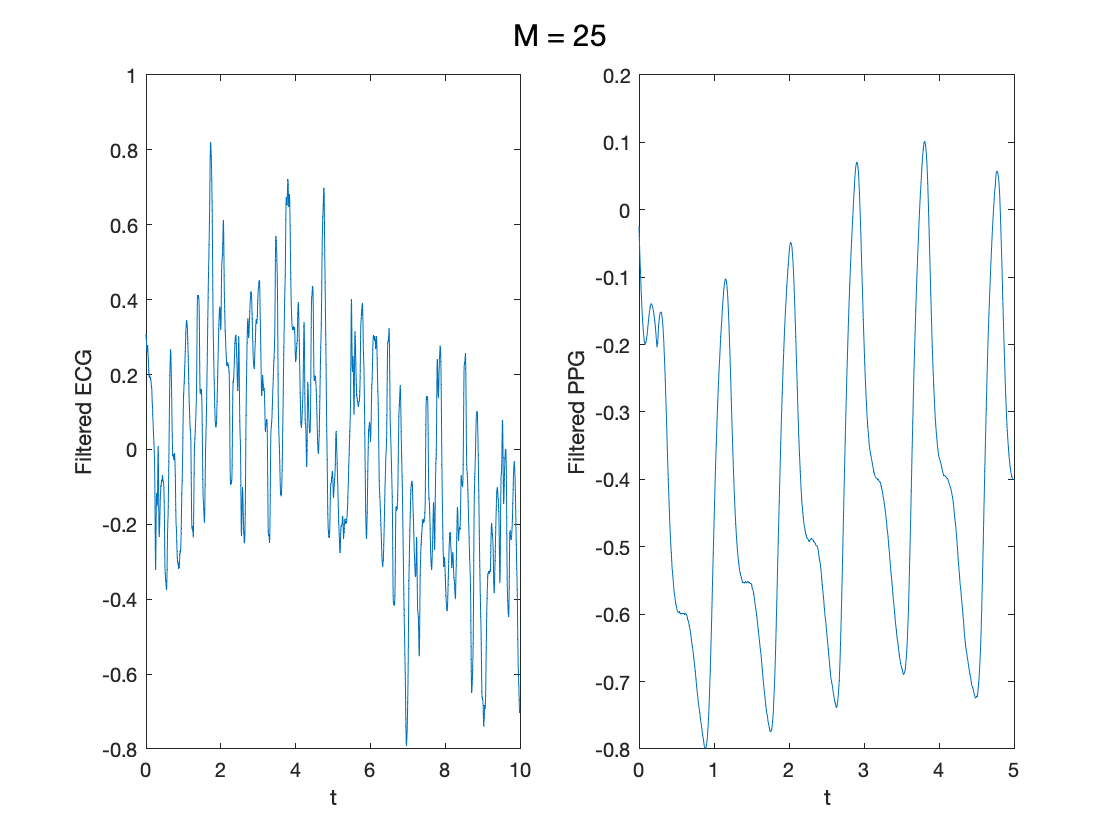

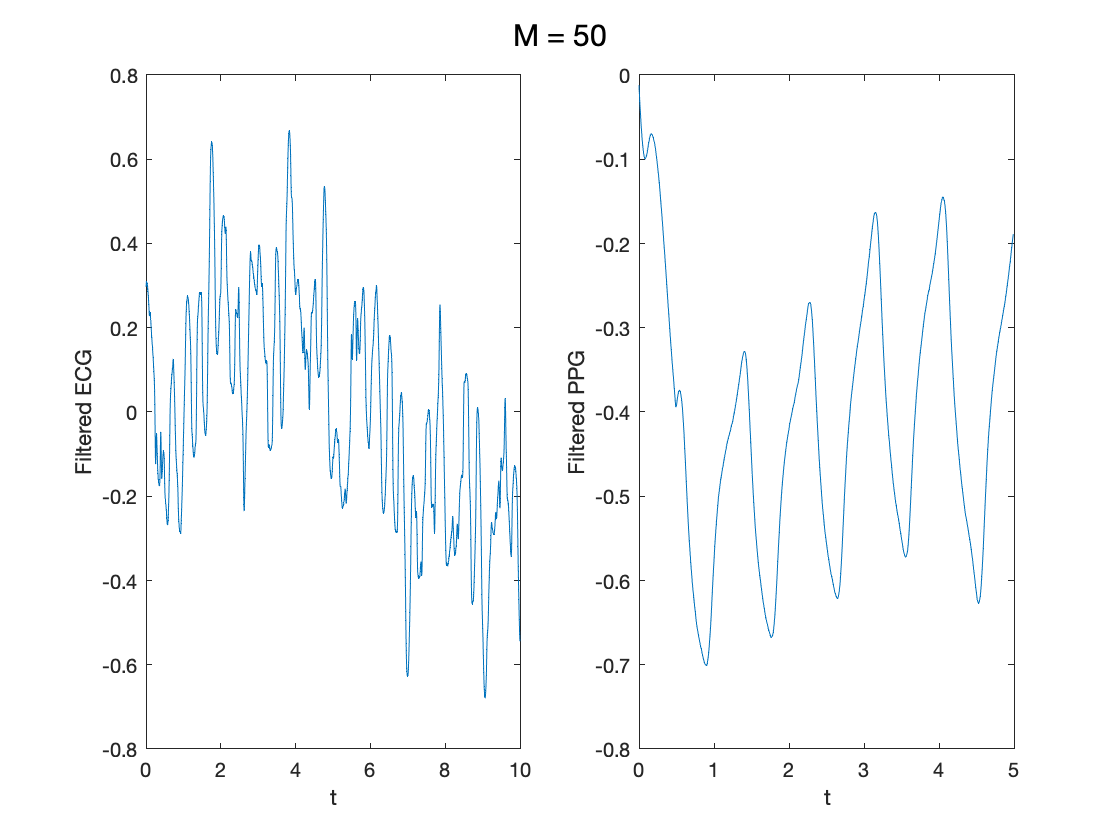

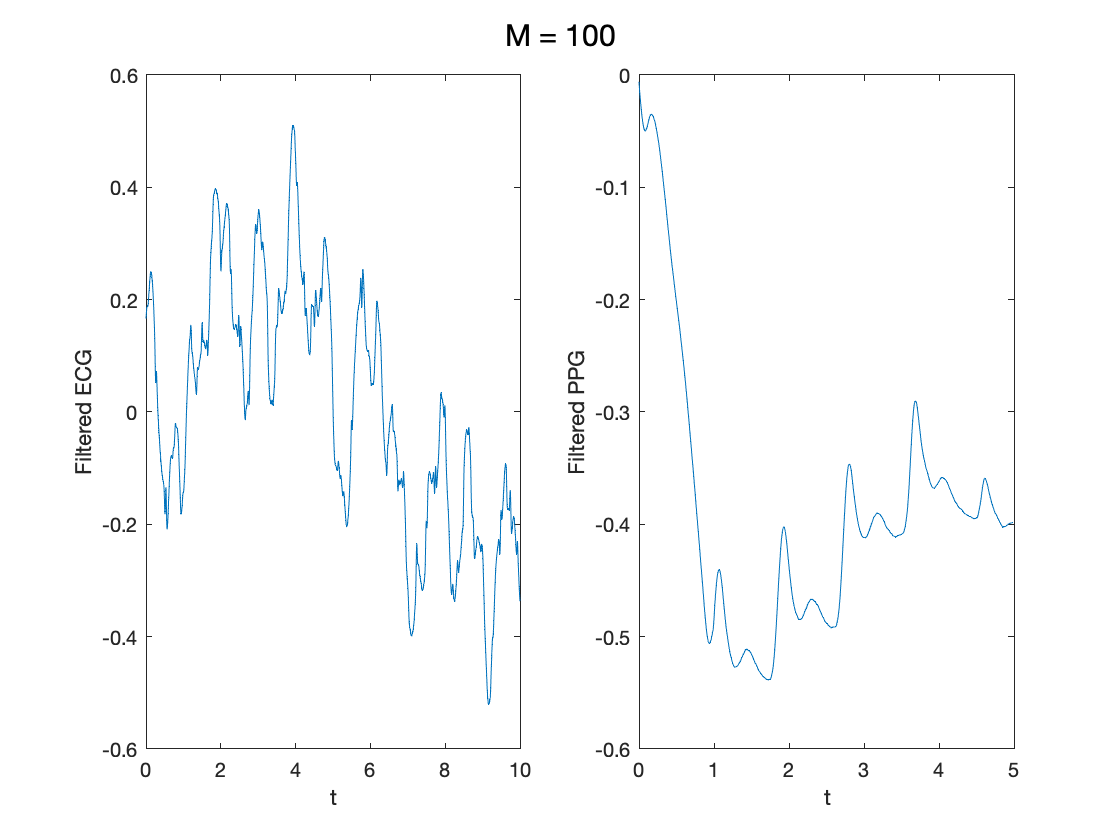

% transforming ECG and PPG signals to the frequency domain
ecg_dtft = dtft(ecg_rang_signal, ecg_n, w);
ppg_dtft = dtft(ppg_random, ppg_n, w);
    
for i = 1:l
    Mi = M_values(i);
    Hw_Mi = Hw_M(Mi);
    
    filtered_ecg = real(dtift(ecg_dtft .* Hw_Mi, w, ecg_n));
    filtered_ppg = real(dtift(ppg_dtft .* Hw_Mi, w, ppg_n));
    
    figure;
    subplot(1, 2, 1);
    plot(ecg_t, filtered_ecg); xlabel("t"); ylabel("Filtered ECG");
    subplot(1, 2, 2);
    plot(ppg_t, filtered_ppg); xlabel("t"); ylabel("Filtered PPG");
    sgtitle("M = " + Mi);
end

We can observe that with an increase in the value of $M$, the filtered ECG and PPG signals start becoming more smooth and less fluctuating. The higher frequency components of both signals are filtered out as we keep increasing $M$.

Q2:

First order derivative filter

(a) Difference equation


$$y[n] = x[n] - x[n-1]$$


(b) Transfer function

Taking z-transform,


$$\Rightarrow Y(z) = X(z)\cdot(1 - z^{-1})$$



$$\Rightarrow H(z) = \frac{Y(z)}{X(z)} = \frac{(z - 1)}{z}$$


(c) Frequency Response

Replacing $z$ with $e^{j\omega}$


$$\Rightarrow H(e^{j\omega}) = 1 - e^{-j\omega}$$


(e) Poles and Zeros

1 pole at $z = 0$, 1 zero at $z = 1$

Second order derivative filter

(a) Difference equation


$$y[n] = x[n] - 2\cdot x[n-1] + x[n-2]$$


(b) Transfer function

Taking z-transform,


$$Y(z) = X(z)\cdot (1 - 2z^{-1} + z^{-2})$$



$$\Rightarrow H(z) = \frac{Y(z)}{X(z)} = \frac{(z-1)^2}{z^2}$$


(c) Frequency Response

Replacing $z$ with $e^{j\omega}$


$$H(e^{j\omega}) = 1 - 2e^{-j\omega} + e^{-j2\omega}$$



$$\Rightarrow H(e^{j\omega}) = (1 - e^{-j\omega})^2$$


(e) Poles and Zeros

2 poles at $z = 0$, 2 zeros at $z = 1$

Central derivative filter

(a) Difference equation


$$y[n] = x[n] - x[n-2]$$


(b) Transfer function

Taking z-transform,


$$Y(z) = X(z)\cdot (1 - z^{-2})$$



$$\Rightarrow H(z) = \frac{Y(z)}{X(z)} = \frac{(z^2-1)}{z}$$


(c) Frequency Response

Replacing $z$ with $e^{j\omega}$


$$\Rightarrow H(e^{j\omega}) = 1 - e^{-j2\omega}$$


(e) Poles and Zeros

1 pole at $z = 0$, 2 zeros at $z = 1$and $z = -1$

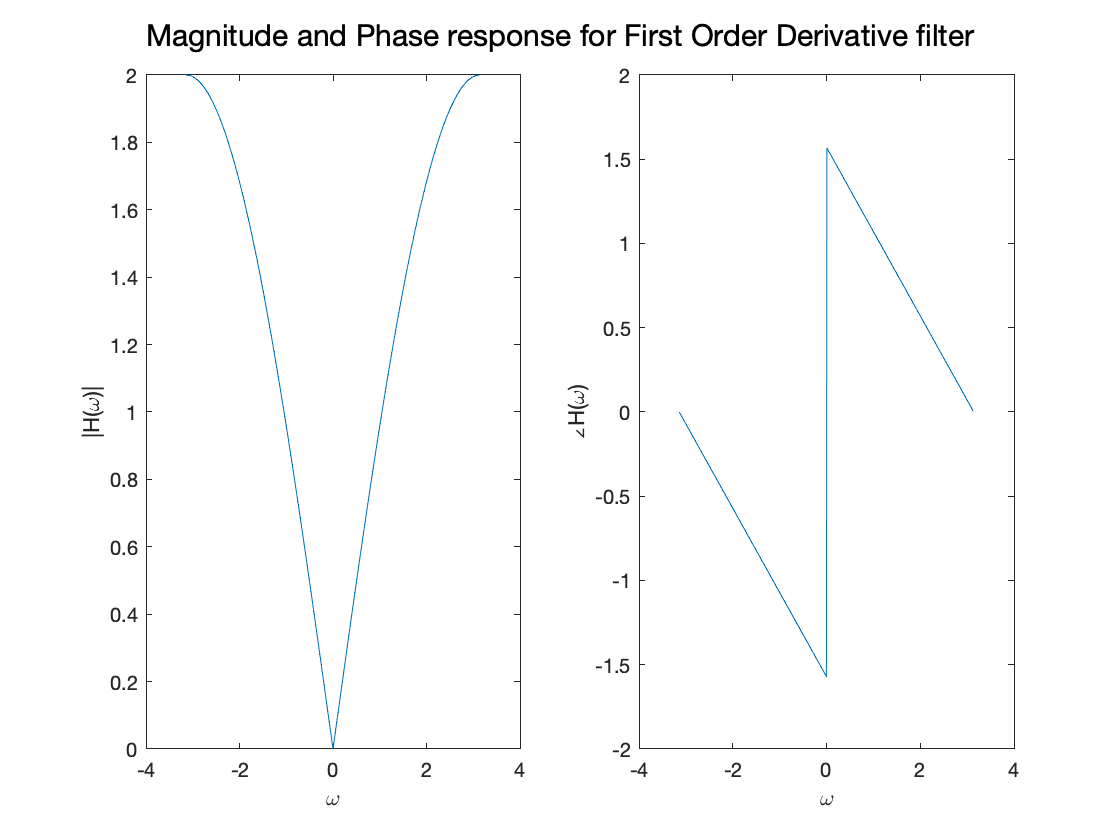

% (d) magnitude and phase response
first_order_freq_resp = 1 - exp(-1j .* w);
second_order_freq_resp = (1 - exp(-1j .* w)) .^ 2;
central_freq_resp = 1 - exp(-2j .* w);

figure;
subplot(1, 2, 1);
plot(w, abs(first_order_freq_resp)); xlabel("\omega"); ylabel("|H(\omega)|");
subplot(1, 2, 2);
plot(w, angle(first_order_freq_resp)); xlabel("\omega"); ylabel("\angleH(\omega)");
sgtitle("Magnitude and Phase response for First Order Derivative filter");

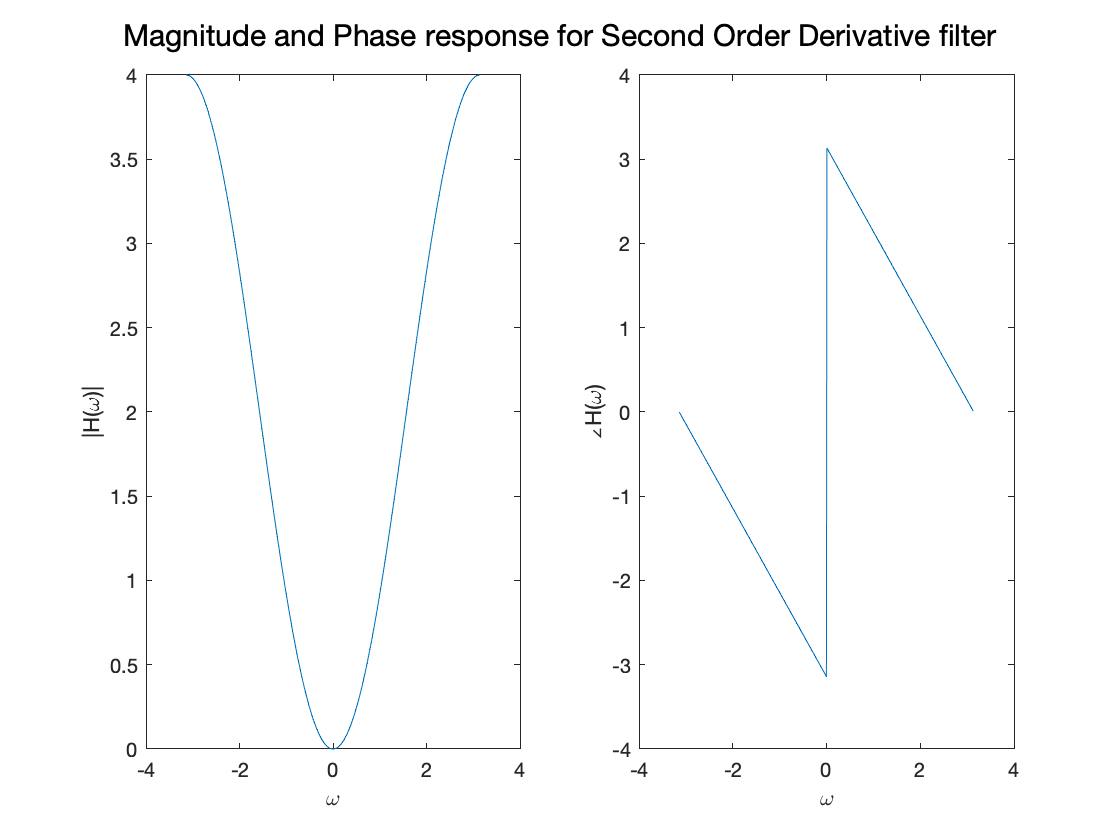

figure;
subplot(1, 2, 1);
plot(w, abs(second_order_freq_resp)); xlabel("\omega"); ylabel("|H(\omega)|");
subplot(1, 2, 2);
plot(w, angle(second_order_freq_resp)); xlabel("\omega"); ylabel("\angleH(\omega)");
sgtitle("Magnitude and Phase response for Second Order Derivative filter");

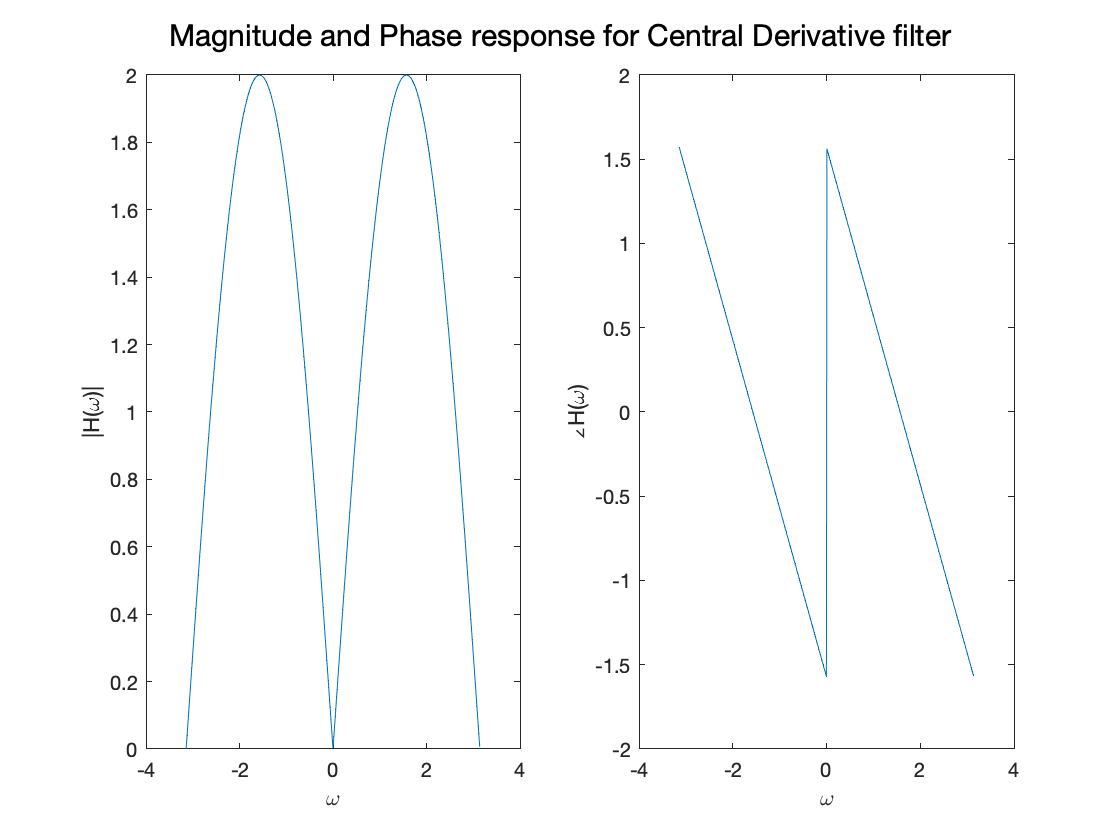

figure;
subplot(1, 2, 1);
plot(w, abs(central_freq_resp)); xlabel("\omega"); ylabel("|H(\omega)|");
subplot(1, 2, 2);
plot(w, angle(central_freq_resp)); xlabel("\omega"); ylabel("\angleH(\omega)");
sgtitle("Magnitude and Phase response for Central Derivative filter");

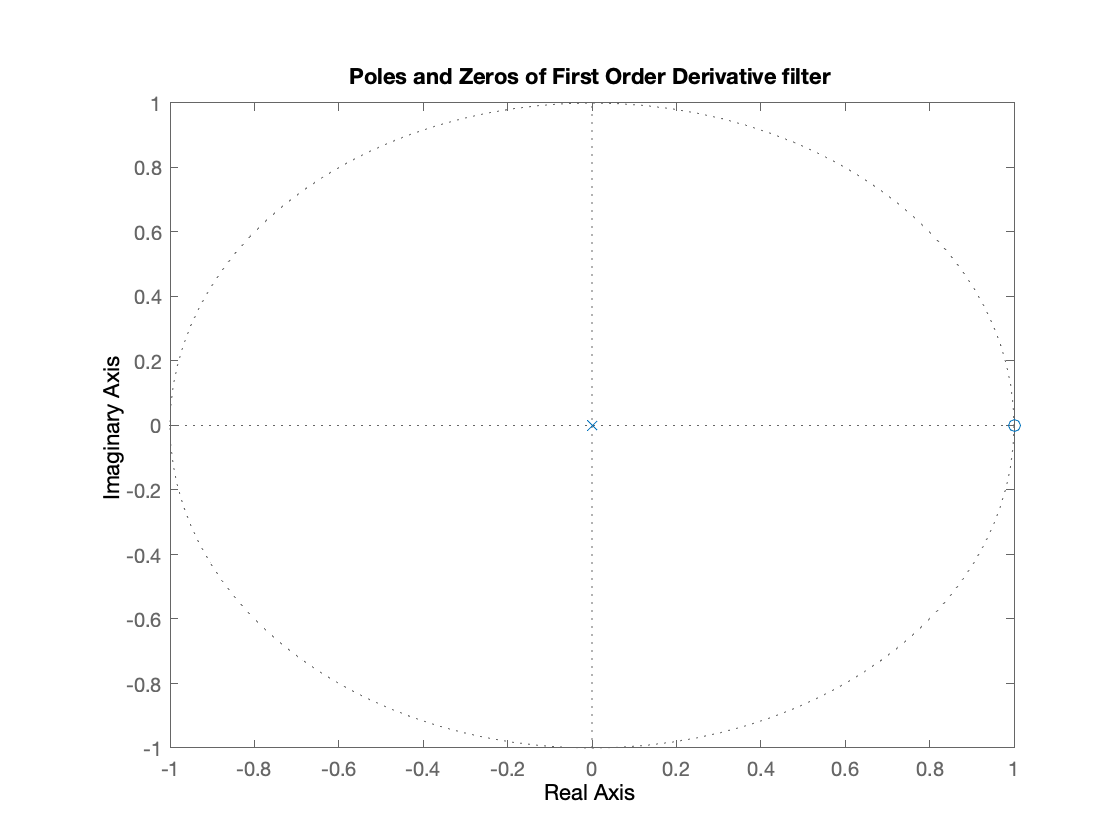

% (f) sketching poles and zeros
z = tf('z');

% defining transfer functions for derivative filters
first_order_tf = (z - 1)/z;
second_order_tf = ((z - 1)^2)/(z^2);
central_tf = ((z^2) - 1)/z;

figure;
pzplot(first_order_tf); title("Poles and Zeros of First Order Derivative filter");

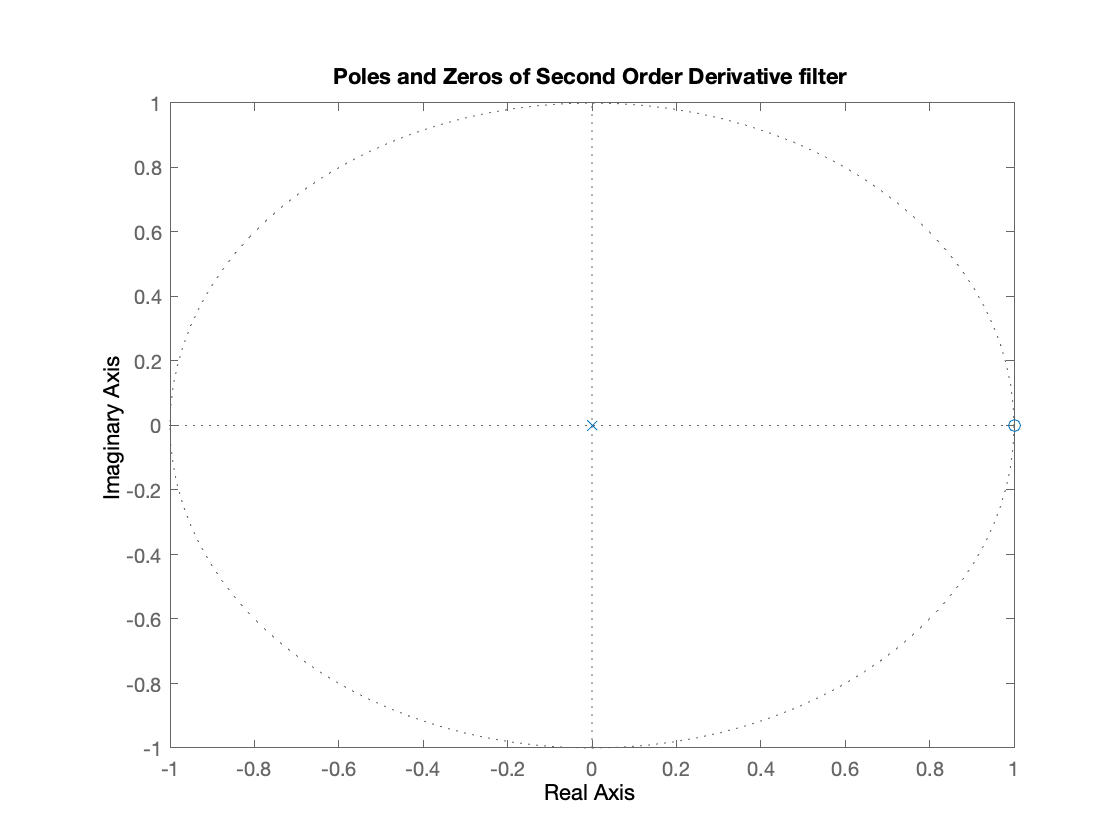

pzplot(second_order_tf); title("Poles and Zeros of Second Order Derivative filter");

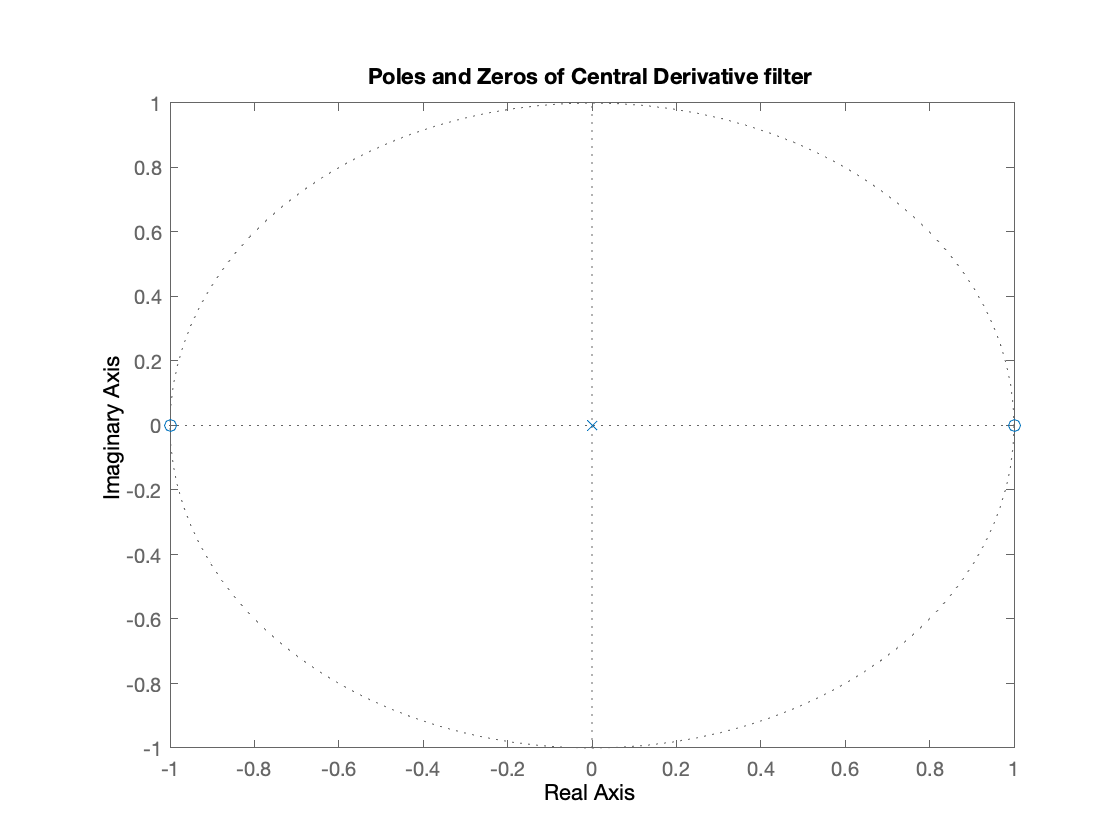

pzplot(central_tf); title("Poles and Zeros of Central Derivative filter");

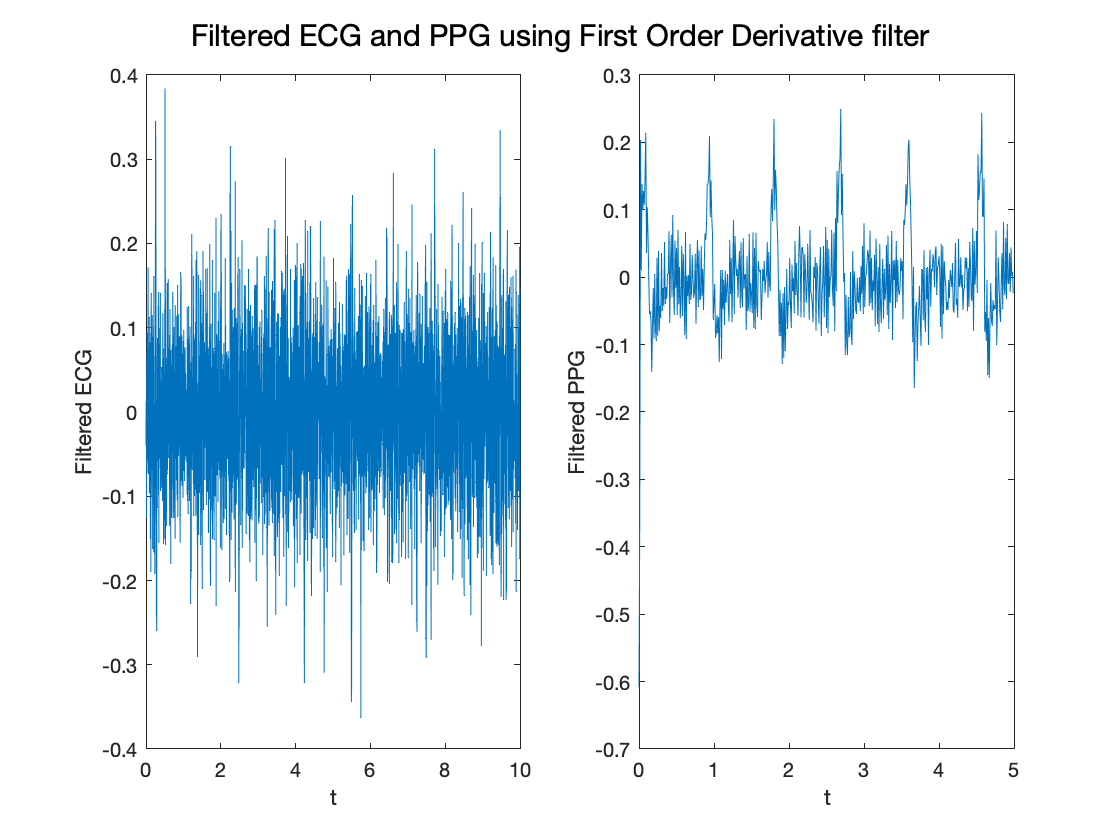

% (g)
ecg_filtered_first_order = real(dtift(ecg_dtft .* first_order_freq_resp, w, ecg_n));
ecg_filtered_second_order = real(dtift(ecg_dtft .* second_order_freq_resp, w, ecg_n));
ecg_filtered_central = real(dtift(ecg_dtft .* central_freq_resp, w, ecg_n));

ppg_filtered_first_order = real(dtift(ppg_dtft .* first_order_freq_resp, w, ppg_n));
ppg_filtered_second_order = real(dtift(ppg_dtft .* second_order_freq_resp, w, ppg_n));
ppg_filtered_central = real(dtift(ppg_dtft .* central_freq_resp, w, ppg_n));

figure;
subplot(1, 2, 1);
plot(ecg_t, ecg_filtered_first_order); xlabel("t"); ylabel("Filtered ECG");
subplot(1, 2, 2);
plot(ppg_t, ppg_filtered_first_order); xlabel("t"); ylabel("Filtered PPG");
sgtitle("Filtered ECG and PPG using First Order Derivative filter");

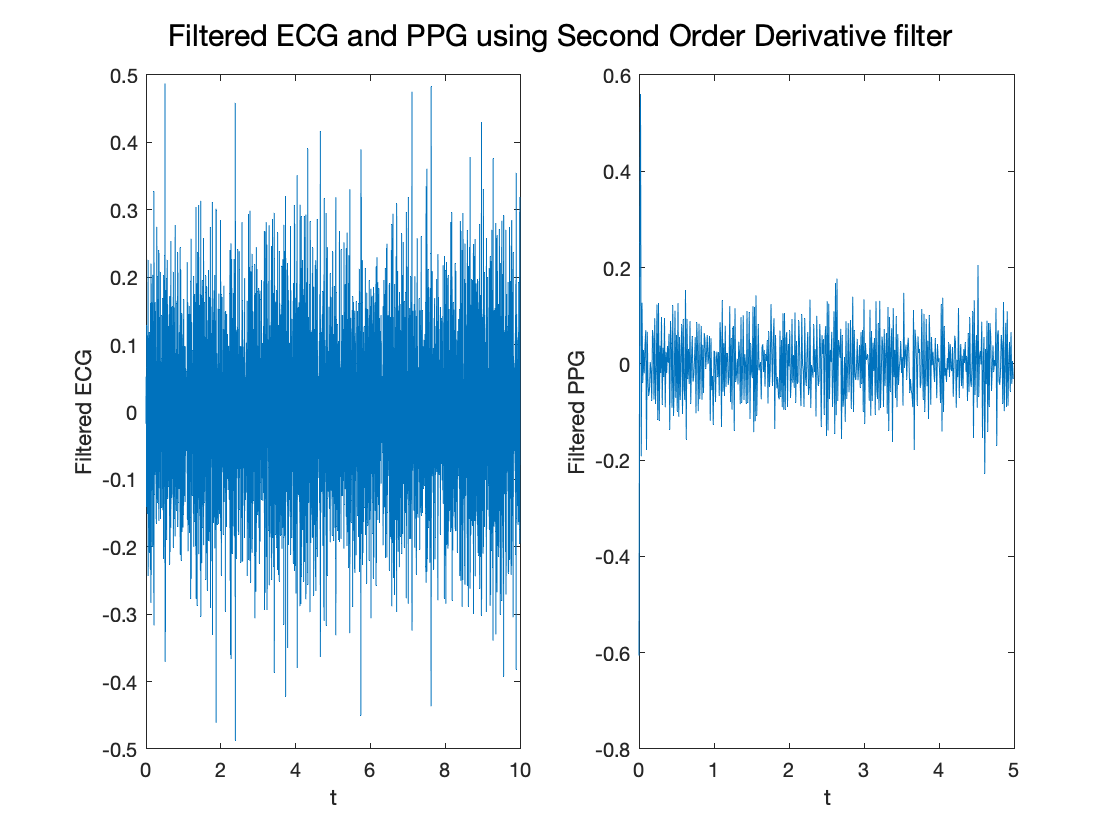

figure;
subplot(1, 2, 1);
plot(ecg_t, ecg_filtered_second_order); xlabel("t"); ylabel("Filtered ECG");
subplot(1, 2, 2);
plot(ppg_t, ppg_filtered_second_order); xlabel("t"); ylabel("Filtered PPG");
sgtitle("Filtered ECG and PPG using Second Order Derivative filter");

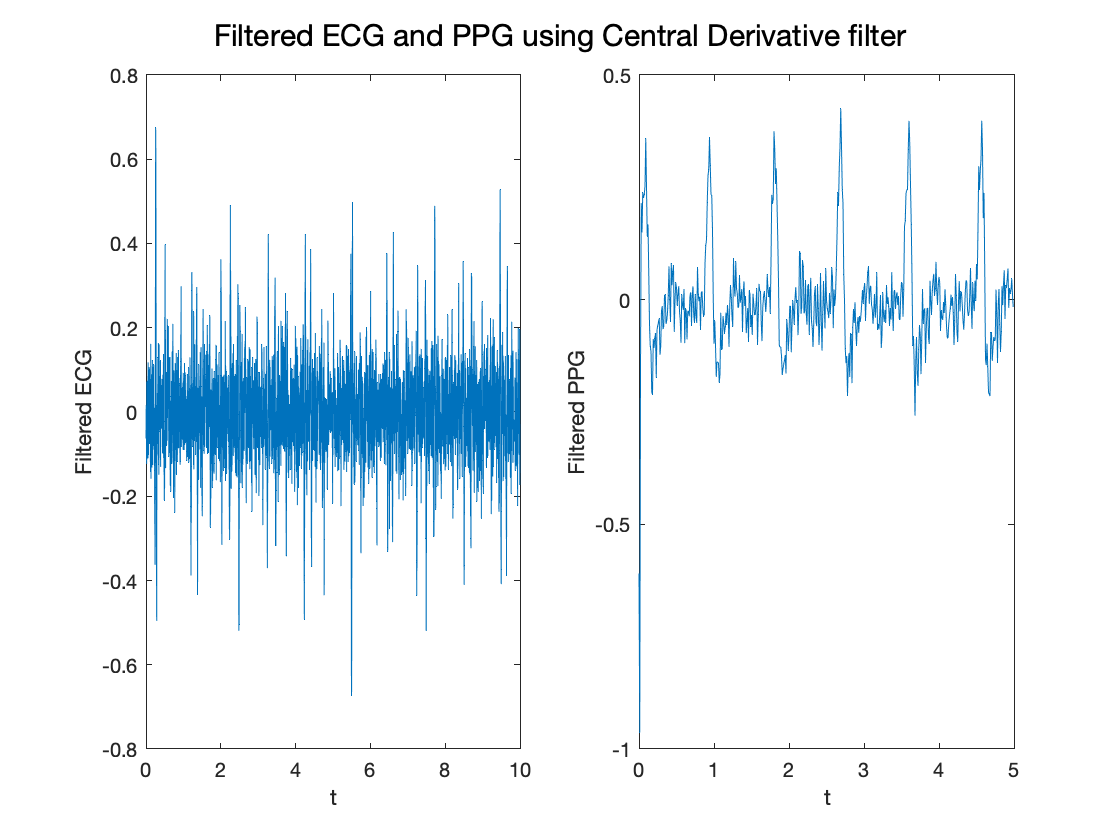

figure;
subplot(1, 2, 1);
plot(ecg_t, ecg_filtered_central); xlabel("t"); ylabel("Filtered ECG");
subplot(1, 2, 2);
plot(ppg_t, ppg_filtered_central); xlabel("t"); ylabel("Filtered PPG");
sgtitle("Filtered ECG and PPG using Central Derivative filter");

The second order derivative filter removes more of the lower frequency components as compared to the first order derivative filter. In addition, the central derivative filter preserves the lower frequency components as compared to the second roder derivative filter, while removing higher frequency comonents, thus acting like a combination of the first and second order derivative filters.

Q3:

Simple first order IIR Filter:


$$y[n] = \alpha_1y[n-1] + \beta_0x[n]$$


assuming $\beta_o = 1$


$$y[n] = \alpha y[n-1] + x[n]$$


Obtaining the Transfer Function by taking z-transform:


$$H(z) = \frac{Y(z)}{X(z)} = \frac{1}{1 - \alpha z^{-1}}$$


Replacing $z$ with $e^{j\omega}$ to get the Frequency Response:


$$H(e^{j\omega}) = \frac{1}{1 - \alpha e^{-j\omega}}$$


Taking the inverse z-transform, we get the impulse response:


$$h[n] = \alpha^{n}\cdot u[n]$$


Clearly, for stability, we must have $|\alpha| \le 1$

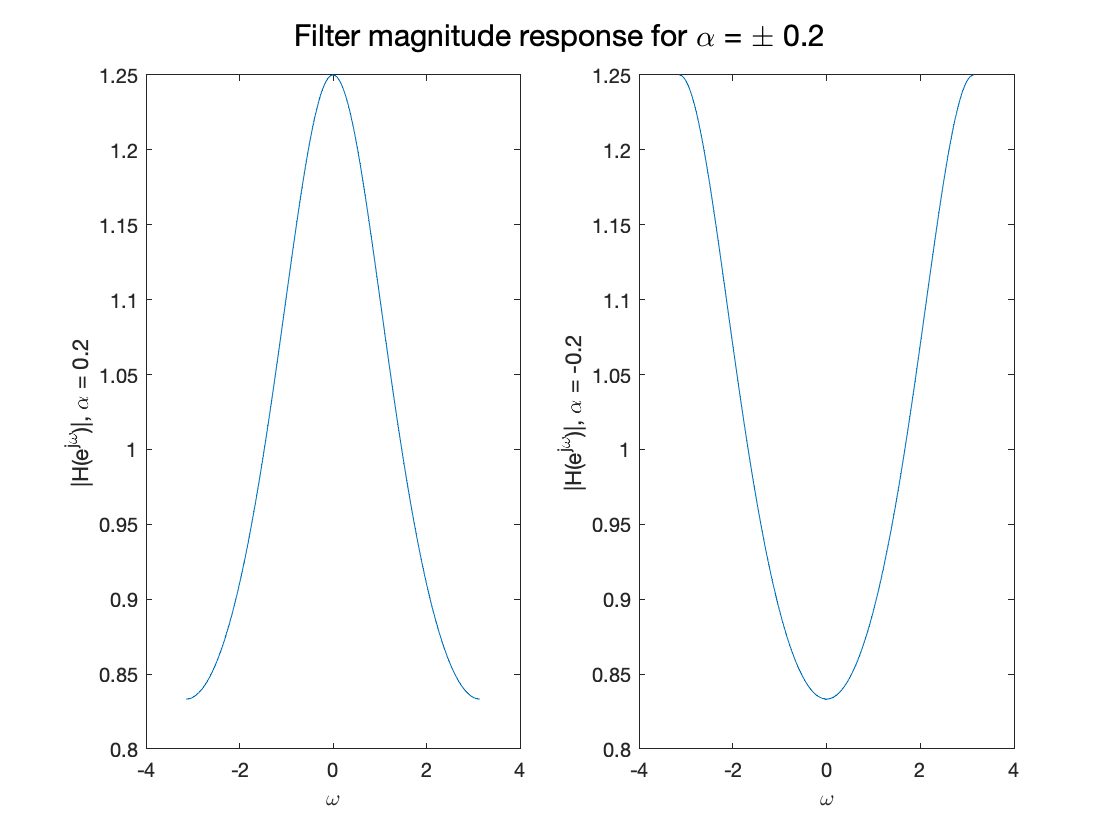

% defining the IIR Filter frequency response
Hw_alpha = @(alpha) 1 ./ (1 - alpha .* exp(-1j .* w));

% alpha = +0.2 & -0.2
Hw1 = Hw_alpha(0.2);
Hw2 = Hw_alpha(-0.2);

figure;
subplot(1, 2, 1);
plot(w, abs(Hw1));
xlabel("\omega"); ylabel("|H(e^{j\omega})|, \alpha = 0.2");
subplot(1, 2, 2);
plot(w, abs(Hw2));
xlabel("\omega"); ylabel("|H(e^{j\omega})|, \alpha = -0.2");
sgtitle("Filter magnitude response for \alpha = \pm 0.2");

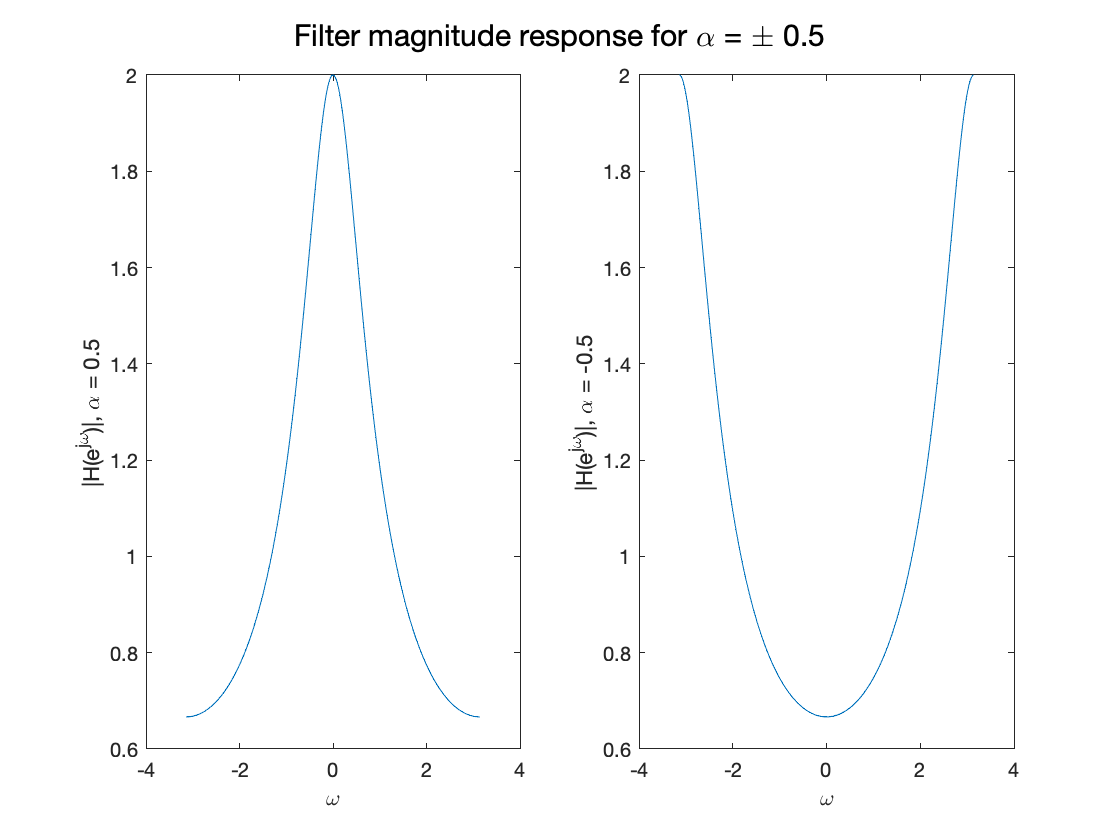

% alpha = +0.5 & -0.5
Hw1 = Hw_alpha(0.5);
Hw2 = Hw_alpha(-0.5);

figure;
subplot(1, 2, 1);
plot(w, abs(Hw1));
xlabel("\omega"); ylabel("|H(e^{j\omega})|, \alpha = 0.5");
subplot(1, 2, 2);
plot(w, abs(Hw2));
xlabel("\omega"); ylabel("|H(e^{j\omega})|, \alpha = -0.5");
sgtitle("Filter magnitude response for \alpha = \pm 0.5");

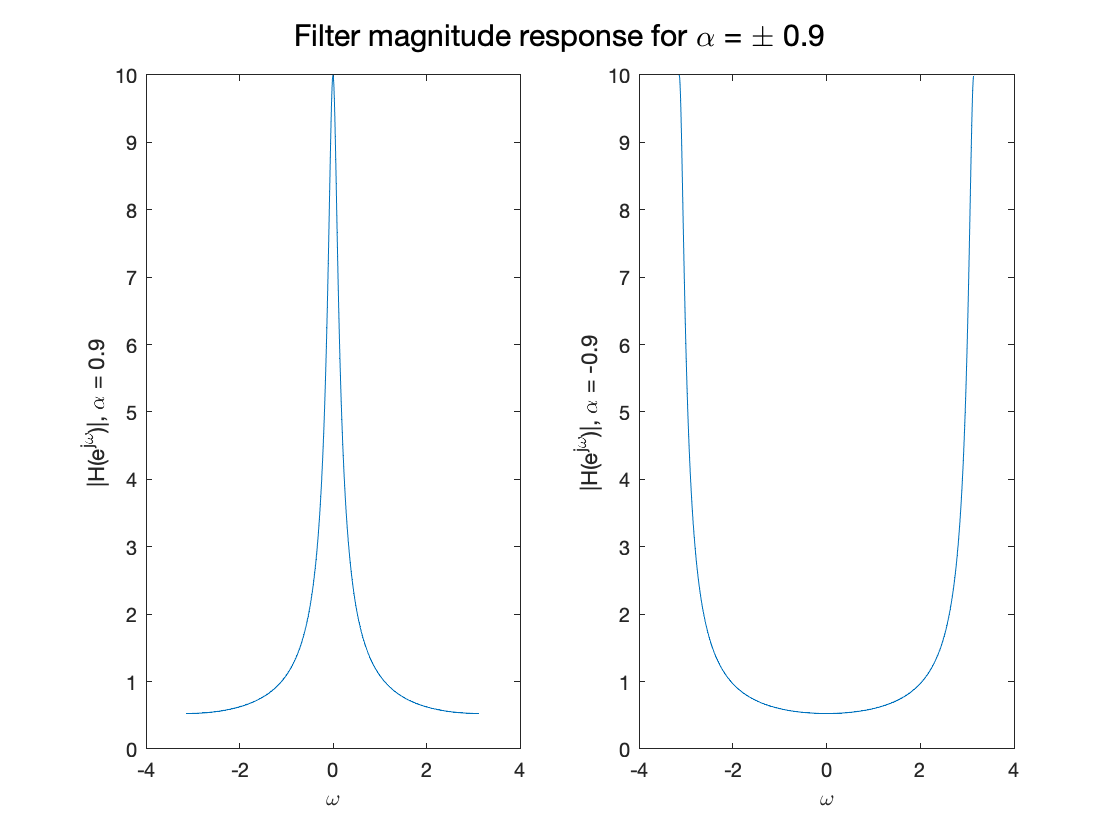

% alpha = +0.9 & -0.9
Hw1 = Hw_alpha(0.9);
Hw2 = Hw_alpha(-0.9);

figure;
subplot(1, 2, 1);
plot(w, abs(Hw1));
xlabel("\omega"); ylabel("|H(e^{j\omega})|, \alpha = 0.9");
subplot(1, 2, 2);
plot(w, abs(Hw2));
xlabel("\omega"); ylabel("|H(e^{j\omega})|, \alpha = -0.9");
sgtitle("Filter magnitude response for \alpha = \pm 0.9");

It can be observed from the above plots that **positive values of **$\alpha$ **result in a Low Pass Filter**, whereas **negative values of **$\alpha$ **result in a High Pass Filter**. An increase in the absolute value of $\alpha$ (i.e. $|\alpha|$), makes the filter *sharper*, i.e.limits the range of frequencies that are allowed by the filter.